# Import data from spreadsheet

Script for importing data from the following spreadsheet:

Auto-generated by MATLAB on 05-Apr-2021 11:38:46

## Set up the Import Options and import the data

opts = spreadsheetImportOptions("NumVariables", 12);

% Specify sheet and range
opts.Sheet = "Arkusz1";
opts.DataRange = "E16:P26";

% Specify column names and types
opts.VariableNames = ["NapiecieZasilania", "PradJalowy", "PradCzynny", "PradBierny", "WychylenieMiernika", "StalaMiernika", "MocZmierzona", "StratyMocyWMierniku", "StratyMocyWTransformatorze", "StratyMocyWUzwojeniu", "StratyMocyWZelazie", "WspolczynnikMocy"];
opts.VariableTypes = ["double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double"];

% Import the data
tbl = readtable("C:\Users\arekj\Documents\MATLAB\PE\Tabele.xlsx", opts, "UseExcel", false);

## Convert to output type

NapiecieZasilania = tbl.NapiecieZasilania;
PradJalowy = tbl.PradJalowy;
PradCzynny = tbl.PradCzynny;
PradBierny = tbl.PradBierny;
WychylenieMiernika = tbl.WychylenieMiernika;
StalaMiernika = tbl.StalaMiernika;
MocZmierzona = tbl.MocZmierzona;
StratyMocyWMierniku = tbl.StratyMocyWMierniku;
StratyMocyWTransformatorze = tbl.StratyMocyWTransformatorze;
StratyMocyWUzwojeniu = tbl.StratyMocyWUzwojeniu;
StratyMocyWZelazie = tbl.StratyMocyWZelazie;
WspolczynnikMocy = tbl.WspolczynnikMocy;

## Clear temporary variables

clear opts tbl

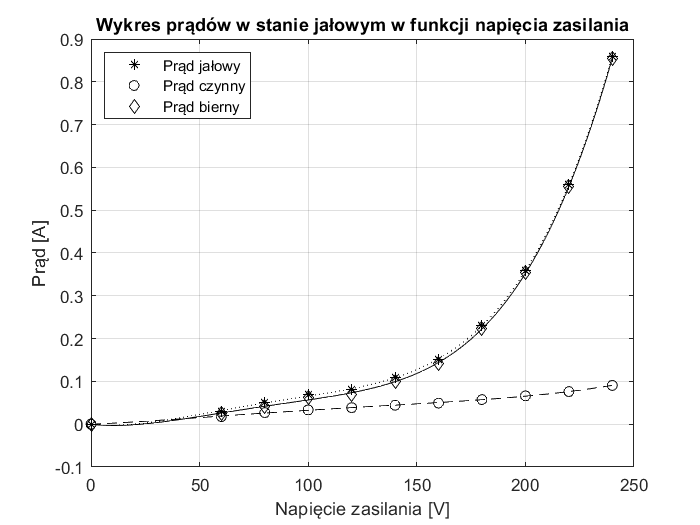

plot(NapiecieZasilania,PradJalowy,'k*')
hold on;
plot(NapiecieZasilania,PradCzynny,'ko')
plot(NapiecieZasilania,PradBierny,'kd')
x1=linspace(0,240);
p1=polyfit(NapiecieZasilania,PradJalowy,4);
p2=polyfit(NapiecieZasilania,PradCzynny,4);
p3=polyfit(NapiecieZasilania,PradBierny,4);
PradJalowyApr=polyval(p1,x1);
PradCzynnyApr=polyval(p2,x1);
PradBiernyApr=polyval(p3,x1);
plot(x1,PradJalowyApr,'k:');
plot(x1,PradCzynnyApr,'k--');
plot(x1,PradBiernyApr,'k-');
hold off;
title("Wykres prądów w stanie jałowym w funkcji napięcia zasilania");
xlabel("Napięcie zasilania [V]");
ylabel("Prąd [A]");
legend("Prąd jałowy","Prąd czynny", "Prąd bierny",'Location','northwest');
grid on;

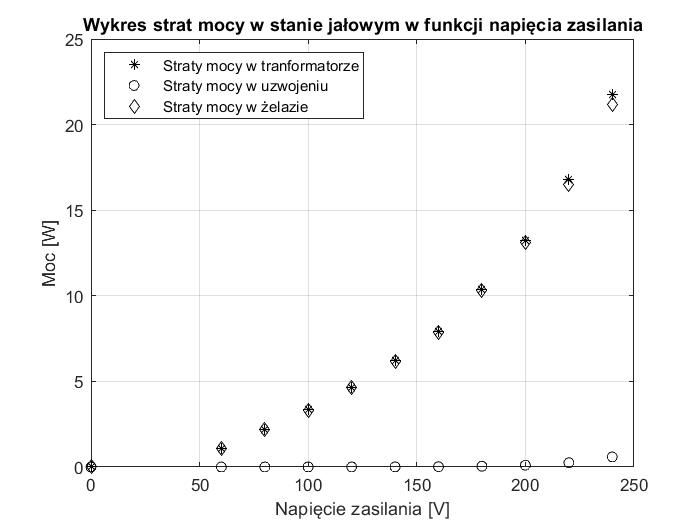

plot(NapiecieZasilania,StratyMocyWTransformatorze,'k*')
hold on;
plot(NapiecieZasilania,StratyMocyWUzwojeniu,'ko')
plot(NapiecieZasilania,StratyMocyWZelazie,'kd')
hold off;
title("Wykres strat mocy w stanie jałowym w funkcji napięcia zasilania");
xlabel("Napięcie zasilania [V]");
ylabel("Moc [W]");
legend("Straty mocy w tranformatorze","Straty mocy w uzwojeniu", "Straty mocy w żelazie",'Location','northwest');
grid on;

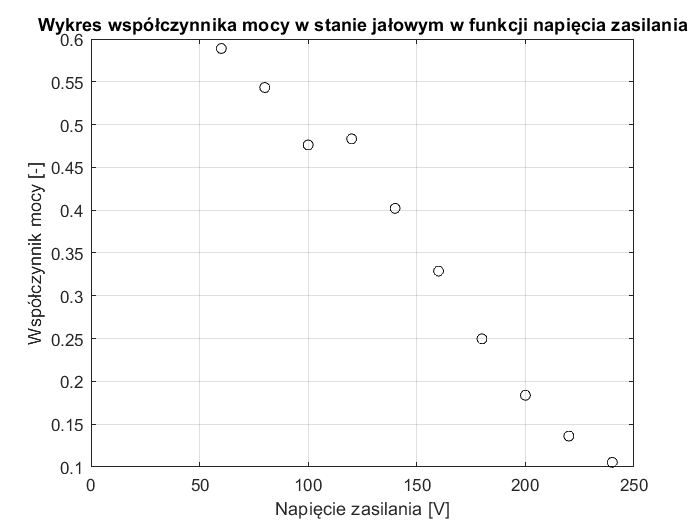

plot(NapiecieZasilania,WspolczynnikMocy,'ko');
xlim([0,250])
title("Wykres współczynnika mocy w stanie jałowym w funkcji napięcia zasilania");
xlabel("Napięcie zasilania [V]");
ylabel("Współczynnik mocy [-]");
grid on;